% Non Linear CSTR Plant Simulation
clear all

% first set of parameters to run the Linear model (linearmodSS)
parameters1 = [102 350 -69.71*10^6 1.205 20.75*10^6 69.71*10^6 8314 801 3137 ...
    851 101 10.1 294 1000 4183 294 339.7022 323.7669 0.0842 0.04377 0.011];

% second set of parameters to run the Nonlinear plant
parameters2 = [102 350 -69.71*10^6 8.01 20.75*10^6 69.71*10^6 8314 801 3137 ...
    851 101 10.1 294 1000 4183 0.0842 339.7022 323.7669  0.04377 0.011];

% steady state values of output and input for plotting purposes
Tr_ss = 339.7022; % degree K
Fj_ss = 0.011; % m^3/s

% create linear spate space model with parameters1
[A,B,C,D] = linearmodSS(parameters1);
eig(A)

ans =    -0.0407
   -0.0005
   -0.0034



sys = ss(A,B,C,D);
Gz = c2d(sys,100); % sample time is in seconds. 
[Amod,Bmod,Cz,Dz] = ssdata(Gz);
tbeng = 0;
deltaT = 100;

P = input('Prediction Horizon [20] ')

P = 100

M = input('Control Horizon [1] ')

M = 1

rsp = input('[Setpoint [0/1/10/20... degree K] ')

rsp = 10

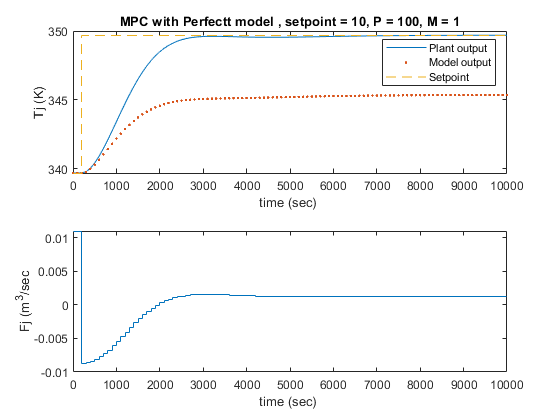

ans = 'Constrained MPC'

dumin = -1


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

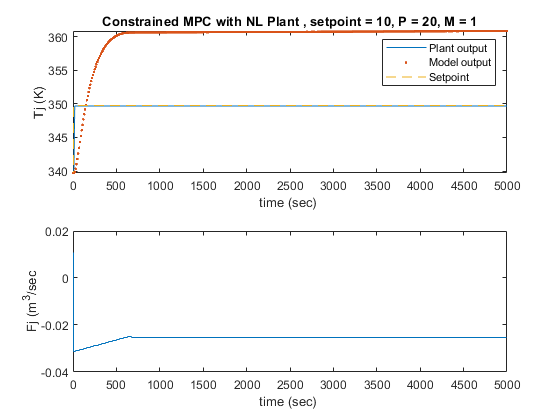

Sf = zeros(P,M); % initial zeros for DMC matrix 

H = 0;
for j=1:P
    H = H + Cz*Amod^(j-1)*Bmod;
    S(j,1) = H;
    Cphi(j,:) = Cz*Amod^(j); 
end

for j=1:M
    zero_DMC = zeros(j-1,1);
    Sf(:,j) = cat(1,zero_DMC,S(1:end+1-j,1)); %DMC 
end
Wu = 0;
Kmat = (Sf'*Sf+Wu)\Sf';

time = tbeng:deltaT:10000; % simulation runs for 5 hours (18000 sec)
x0 = [0;0;0];
%x0 = [0;0;0]; % initial conditions for the states
x(:,1) = x0;
y(1) = Cz*x(:,1); % measured output
xmod(:,1) = x0;
ymod(1) = Cz*xmod(:,1);
u_ini = 0;
d = y - ymod; 

for k = 1:length(time)-1
   
    if k < 3
        r(k) = 0;
        r_sp = ones(P,1)*r(k);
        free_resp = Cphi*xmod(:,k) + S*u_ini + ones(P,1)*d(k); % free response
        
    else
        r(k) = rsp;
        r_sp = ones(P,1)*rsp;
         free_resp = Cphi*xmod(:,k) + S*u(k-1) + ones(P,1)*d(k);
    end
    
     E = r_sp - free_resp; % error term
    uf = Kmat*E; % vector of calculated control moves
    du(k) = uf(1); % implement only first move
    
    if k == 1
        u(k) = u_ini + du(k);
    else
        u(k) = u(k-1) + du(k);
    end
  CSTR = 'NLcstrplant2s';
% [tdummy,xdummy] = ode45(CSTR,[time(k) time(k+1)],x0,u(k),parameters2);
[tdummy,xdummy] = ode45(@(t,x) NLcstrplant2s(t,x,u(k),parameters2), [time(k) time(k+1)], x0);
x0= xdummy(end,:)'; % assigning states variables as input for next iteration
x(:,k+1) = xdummy(end,:)';

y(k+1) = Cz*x(:,k+1); % output as last value of xnew
xmod(:,k+1) = Amod*xmod(:,k) + Bmod*u(k);
ymod(k+1) = Cz*xmod(:,k+1);
d(k+1) = y(k+1) - ymod(k+1); 
    

end
r(k+1) = r(k);
u(k+1) = u(k);
figure(100)
subplot(2,1,1)
plot(time,y+Tr_ss,time,ymod+Tr_ss,'.')
hold on
stairs(time,r+Tr_ss,'--')
hold off
title(['MPC with Perfectt model , setpoint = ', num2str(rsp), ', P = ',num2str(P), ', M = ', num2str(M)])
ylabel('Tj (K)')
xlabel('time (sec) ')
legend('Plant output', 'Model output', 'Setpoint')


subplot(2,1,2)
stairs(time,u+Fj_ss)
ylabel('Fj (m^3/sec')
xlabel('time (sec) ')